**Numerical Methods Midterm Exam 2023 - Solutions**

**__ Marks**

1. The equation,


$$y = \frac{\ln(Ax + B)}{x}$$


is to be fit to the following data:

(a) Linearise the equation to find the values of $A$ and $B$ then plot your fitted equation against the values in the table.

(b) Calculate the correlation coefficient.

% Solution to question 1
x = [1 1.5 2 2.5 3 3.5 4 4.5 5];
y = [1.6134 1.2636 1.0575 0.9180 0.8159 0.7371 0.6742 0.6225 0.5792];

% plot the data
close all
plot (x, y, 'o', 'MarkerEdgeColor','b');
hold on

% (a)
Y = exp(y.*x);
a = polyfit(x, Y, 1);
disp(a);

    3.2704    1.7493



A = a(1);
B = a(2);
yfit = @(c) log(A.*c + B)./c;
X = linspace(1, 5)

X =     1.0000    1.0404    1.0808    1.1212    1.1616    1.2020    1.2424    1.2828    1.3232    1.3636    1.4040    1.4444    1.4848    1.5253    1.5657    1.6061    1.6465    1.6869    1.7273    1.7677    1.8081    1.8485    1.8889    1.9293    1.9697    2.0101    2.0505    2.0909    2.1313    2.1717    2.2121    2.2525    2.2929    2.3333    2.3737    2.4141    2.4545    2.4949    2.5354    2.5758    2.6162    2.6566    2.6970    2.7374    2.7778    2.8182    2.8586    2.8990    2.9394    2.9798


disp(yfit(X))

  Columns 1 through 9

    1.6134    1.5757    1.5402    1.5067    1.4751    1.4451    1.4166    1.3895    1.3637

  Columns 10 through 18

    1.3391    1.3155    1.2930    1.2714    1.2507    1.2309    1.2118    1.1934    1.1757

  Columns 19 through 27

    1.1586    1.1421    1.1262    1.1109    1.0960    1.0816    1.0677    1.0542    1.0411

  Columns 28 through 36

    1.0284    1.0161    1.0041    0.9925    0.9811    0.9701    0.9594    0.9490    0.9388

  Columns 37 through 45

    0.9289    0.9192    0.9098    0.9006    0.8916    0.8829    0.8743    0.8659    0.8578

  Columns 46 through 54

    0.8498    0.8419    0.8343    0.8268    0.8195    0.8123    0.8053    0.7984    0.7916

  Columns 55 through 63

    0.7850    0.7785    0.7722    0.7659    0.7598    0.7538    0.7479    0.7421    0.7364

  Columns 64 through 72

    0.7308    0.7253    0.7199    0.7146    0.7094    0.7043    0.6993    0.6943    0.6895

  Columns 73 through 81

    0.6847    0.6800    0.6753    0.6708 

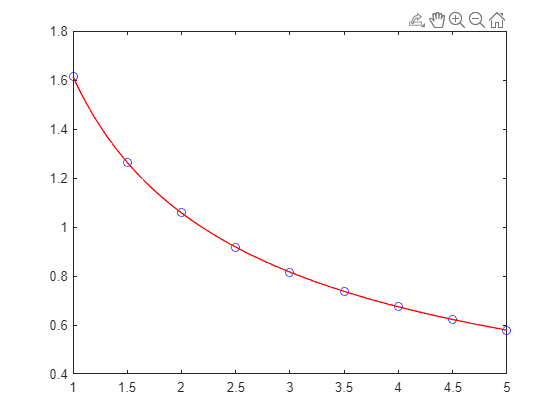

plot(X, yfit(X), 'r');
hold off

% (b)
r = correlation_coefficient(x,y);
disp(r);

   -0.9396



2. The temperature in $^oC$ of a rectangular plate is measured at the following $xy$-locations.

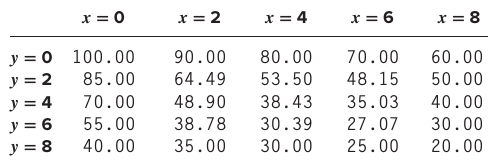

Interpolate the data to find the $xy$-coordinates where the temperature is approximately 28$^oC$.

% Solution to question 2
y_val = 0:2:8;
y = [y_val y_val y_val y_val y_val]';
x = [0 0 0 0 0 2 2 2 2 2 4 4 4 4 4 6 6 6 6 6 8 8 8 8 8]';
c = [100.00 85.00 70.00 55.00 40.00  90.00 64.49 48.90 38.78 35.00  80.00 53.50 38.43 30.39 30.00  70.00 48.15 35.03 27.07 25.00  60.00 50.00 40.00 30.00 20.00]';
% yy = [y_val y_val y_val y_val y_val]';
% xx = [0 0 0 0 0 2 2 2 2 2 4 4 4 4 4 6 6 6 6 6 8 8 8 8 8]';
% cc = [100.00 85.00 70.00 55.00 40.00  90.00 64.49 48.90 38.78 35.00  80.00 53.50 38.43 30.39 30.00  70.00 48.15 35.03 27.07 25.00  60.00 50.00 40.00 30.00 20.00]';
% close all
% plot(yy, xx, 'o');
% disp(size(c));
z = [ones(size(y)) y x];
a = (z'*z)\(z'*c);
disp(a);

   90.2624
   -6.1990
   -3.7192




% create function
c_funct = @(x, y) a(1) + a(2).*x + a(3).*y;
ans_x = 5.77047

ans_x = 5.7705

ans_y = 7.12284

ans_y = 7.1228

disp(c_funct(5.77047, 7.12284))

   28.0000



disp("x =")

x =


disp(ans_x)

    5.7705



disp("y =")

y =


disp(ans_y)

    7.1228



3. Use a triple integral to determine the volume of the region bounded by $y = x^2 + z^2$ and $y = \sqrt{x^2+z^2}$ using:

(a) Any standard Matlab functions.

(b) Romberg integration to within 6 decimal places. Print the number of Romberg iterations required to achieve this accuracy.

% Solution to question 3
% (a)
volumn = @(x, y, z) x.*y.*z;
% y1 = integral

% (b)
romberg_sol = romberg(volumn, 0, 30, 0.5);

Not enough input arguments.

Error in numerical_methods_final_2023 (line 45)
volumn = @(x, y, z) x.*y.*z;

Error in numerical_methods_final_2023>trapezium (line 129)
area = (h/2) * ( f(a) + (2 * sum( f(x(2:end-1)) )) + f(b)) ;

Error in numerical_methods_final_2023>rom

4. Convert the following differential equation into a system of ODEs and solve using any Matlab function based on the initial conditions for $t \in [0,8]$.


$$y(0) = 1, y'(0) = -1, y''(0) = 0, y^{(3)}(0) = -2, y^{(4)}(0) = 0$$


% Solution to question 4
h = 1;
t = 0:h:8;
x1 = 1;
x2 = -1;
x3 = 0;
x4 = -2;
x5 = 0;

func1 = @(t,x1,x2,x3,x4,x5) x2;
func2 = @(t,x1,x2,x3,x4,x5) x3;
func3 = @(t,x1,x2,x3,x4,x5) x4;
func4 = @(t,x1,x2,x3,x4,x5) x5;
func5 = @(t,x1,x2,x3,x4,x5) (3.*x5 + 2.*x4 - x3 - x2 + 5.*x1)./2;

for i = 1:length(t)-1
   x1(i+1) = x1(i) + h.*( func1(t(i) , x1(i) , x2(i), x3(i), x4(i), x5(i)) );
   x2(i+1) = x2(i) + h.*( func2(t(i) , x1(i) , x2(i), x3(i), x4(i), x5(i)) );
   x3(i+1) = x3(i) + h.*( func3(t(i) , x1(i) , x2(i), x3(i), x4(i), x5(i)) );
   x4(i+1) = x4(i) + h.*( func4(t(i) , x1(i) , x2(i), x3(i), x4(i), x5(i)) );
   x5(i+1) = x5(i) + h.*( func5(t(i) , x1(i) , x2(i), x3(i), x4(i), x5(i)) );
end
disp(x1);

    1.0000         0   -1.0000   -4.0000  -11.0000  -23.0000  -39.0000  -53.0000  -49.5000



disp(x2);

   -1.0000   -1.0000   -3.0000   -7.0000  -12.0000  -16.0000  -14.0000    3.5000   46.7500



disp(x3);

         0   -2.0000   -4.0000   -5.0000   -4.0000    2.0000   17.5000   43.2500   59.6250



disp(x4);

   -2.0000   -2.0000   -1.0000    1.0000    6.0000   15.5000   25.7500   16.3750  -80.5625



disp(x5);

         0    1.0000    2.0000    5.0000    9.5000   10.2500   -9.3750  -96.9375 -381.8438



 --- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.

function r = correlation_coefficient(x,y)
r = (length(x) * sum(x .* y) - sum(x) * sum(y)) / (sqrt(length(x) * sum(x .^ 2) - (sum(x) .^ 2)) .* sqrt(length(x) .* sum(y .^ 2) - (sum(y) .^ 2)));
end

function U = poly_interp(x, y, z)
A = [];
n = length(x);
B = y;
for i = 1:n
    for j = 1:n
        A(i,j) = x(i)^(j-1);
    end
end
U = flip(A\B);
end

function A = romberg(func, a, b, tol)
i_max = 1000;
n = 1;
I(1,1) = trapezium(func, a, b, n);  % เพราะ Romberg พื้นฐานมาจาก Richardson Extrapolation และ Richard ก็อิงมาจาก Trapz Rule อีกที
j = 0;
while j < i_max
    j = j + 1;
    n = 2^j;
    I(j+1, 1) = trapezium(func, a, b, n);
    for k=2:j+1
        jj = 2+j-k;
        I(jj,k) = ( ((4^(k-1)) * I(j+1 - (k-2), k-1)) - I(j- (k-2), k-1) )/ ((4^(k-1)) -1) ;% Romberg formula.
    end
    ea = abs((I(1, k) - I(2, k-1))/ I(1,k) ) * 100;        % Approximate percentage error.
    disp(ea);
    if ea < tol               % If statement that breaks the loop if the error is less than the tolerance.
        disp('error less than the tolerance. STOP!')
        break
    end
end
A = I(jj,k);               % Final output.
if j == i_max                  % If maximum iterations are reached display a warning to the user.
    disp('max iteration reached')
end
end

function area = trapezium( f, a, b, n )
%{
Implements the composite trapezium rule:
A = (h/2)*(f(x0)+2*f(x1)+2*f(x2)+...+f(xn))
%}
format rational
% Step size
h = (b - a)/ n ;

format default
% x-values at which to evaluate function
x = a : h : b ;

% Vectorised formula for integral
area = (h/2) * ( f(a) + (2 * sum( f(x(2:end-1)) )) + f(b)) ;
end